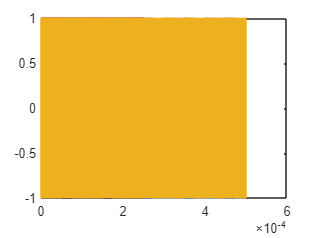

clear all;
close all;

% Parameters
fs = 50e6;          % Sampling frequency in Hz
f_sin = 100e3;        % Sinusoid frequency in Hz
t = 0:1/fs:0.5e-3;        % Time vector
bits = 16;

signal_amplitude = 0.001; %Signal output amplitude[V]
signal_phase = pi/16;             % Phase


% Generate 16-bit fixed-point sinusoid
sinusoid = sin(2 * pi * f_sin * t );
cosinusoid = cos(2 * pi * f_sin * t);
signal = signal_amplitude * sin(2 * pi * f_sin * t + signal_phase);

sinusoid = 2*rem(1:length(t),2) - 1;
cosinusoid = [ones(1,(length(t)-1)/2), 2*rem(0:(length(t)-1)/2,2)-1];
signal = [ones(1,(length(t)-1)/2), -ones(1,(length(t)+1)/2)];

% Quantize to 16 bits

quantized_sinusoid = fi(sinusoid, 1, bits, bits-1);
quantized_cosinusoid = fi(cosinusoid, 1, bits, bits-1);
quantized_signal = fi(signal, 1, bits, bits-1);


figure()
plot(t,quantized_signal);
hold on
plot(t, quantized_cosinusoid);
plot(t,quantized_sinusoid);

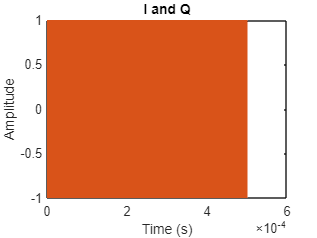

%DEMODULATION

%Input multiplication with 32 bit output, Floor rounding and saturation
%If the output is reduced 
input_multiplication = fimath('ProductMode','FullPrecision');

quantized_signal.fimath = input_multiplication;
quantized_cosinusoid.fimath = input_multiplication;
quantized_sinusoid.fimath = input_multiplication;

Q = quantized_signal .* quantized_sinusoid;
I = quantized_signal .* quantized_cosinusoid;

figure()
plot(t, I, 'LineWidth', 1);
hold on;
plot(t, Q, 'LineWidth', 1);
title('I and Q');
xlabel('Time (s)');
ylabel('Amplitude');

%FILTER PARAMETER%

%%calculate wc from alpha, alpha = 1-(1-sin(wc))/cos(wc);
%wc = asec((-alpha^2 + 2*alpha-2)/(2*(alpha-1)));
%fc=wc/(2*pi)*fs
%tau=1/(2*pi*fc)
Time_per_step = 0.01;
tau = Time_per_step/6.91; %for 99.9% settling of first order filter
fc = 1/(2*pi*tau);
wc = fc/fs * 2 * pi;
alpha = 1-(1-sin(wc))/cos(wc);
%alpha = 2^-26

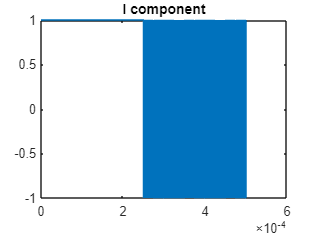

%IDEAL FILTER%

tustin_num = alpha/2*[1 1];
tustin_den = [1 -(1-alpha)];
tustin_iir = dsp.IIRFilter('Numerator',tustin_num,'Denominator',tustin_den);
%fvtool(tustin_iir,'Fs',fs);

I_tustin = tustin_iir(double(I'))';
reset(tustin_iir)
Q_tustin = tustin_iir(double(Q'))';

figure()
plot(t, double(I));
title('I component');

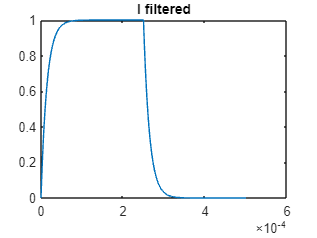

figure()
plot(t, I_tustin);
title('I filtered');

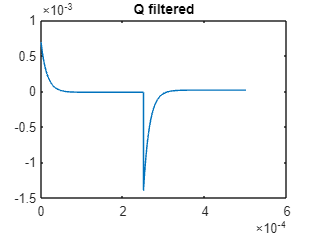

figure()
plot(t, Q_tustin);
title('Q filtered');


output_tustin = Q_tustin(end) + j*I_tustin(end);
output_tustin = 2 * output_tustin;
amplitude = abs(output_tustin)

amplitude = 4.3203e-05

phase = angle(output_tustin)*180/pi

phase = 45.0591

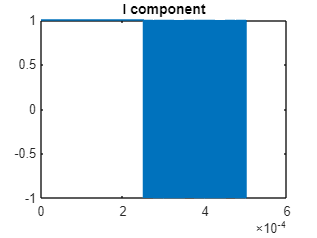

%MATLAB FIXED FILTER%

[Q_tustin_pipelined, I_tustin_pipelined]  = tustin_pipeline_fp_opt(Q, I, alpha);

figure()
plot(t, double(I));
title('I component');

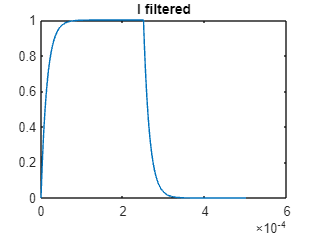

figure()
plot(t, I_tustin_pipelined);
title('I filtered');

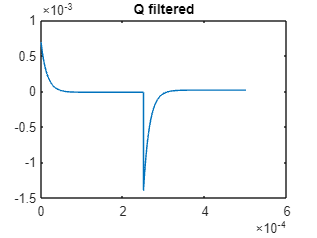

figure()
plot(t, Q_tustin_pipelined);
title('Q filtered');

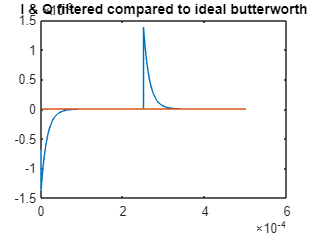


figure()
plot(t, [0, I_tustin(1:end-1)]-I_tustin_pipelined);
hold on;
plot(t, Q_tustin-Q_tustin_pipelined);
title('I & Q filtered compared to ideal butterworth');


% Calculate phase and amplitude
output_tustin_pipelined = double(Q_tustin_pipelined(end)) + j*double(I_tustin_pipelined(end));
output_tustin_pipelined = 2 * output_tustin_pipelined;
amplitude_pipelined = abs(output_tustin_pipelined)

amplitude_pipelined = 4.3143e-05

phase_pipelined = angle(output_tustin_pipelined)*180/pi

phase_pipelined = 45.0910

% Pass the data to the testbench

disp('Da mettere nella testBench per alpha: ');

Da mettere nella testBench per alpha: 


disp(fi(alpha,1,27,26).bin);

000000000010110101000001000



sin_temp = int16(double(quantized_sinusoid)*2^15);
cos_temp = int16(double(quantized_cosinusoid)*2^15);
sig_temp = int16(double(quantized_signal)*2^15);

% Write to text files
writematrix(dec2bin(sin_temp'), 'lockin_sin_ref.txt', 'Delimiter', '\t');
writematrix(dec2bin(cos_temp'), 'lockin_cos_ref.txt', 'Delimiter', '\t');
writematrix(dec2bin(sig_temp'), 'lockin_signal_in.txt', 'Delimiter', '\t');
pause(); 

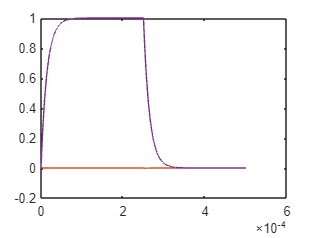

% get the filter result
X_tb_lpf = double(typecast(uint32(readmatrix("lockin_X_out.txt", 'Delimiter', '\t')), 'int32')')*2^-31;
Y_tb_lpf = double(typecast(uint32(readmatrix("lockin_Y_out.txt", 'Delimiter', '\t')), 'int32')')*2^-31;

figure();
plot (t(1:end-2), [Q_tustin_pipelined(1:end-2)])
hold on
plot (t(1:end-2), [X_tb_lpf])
plot (t(1:end-2), [I_tustin_pipelined(1:end-2)])
plot (t(1:end-2), [Y_tb_lpf])


max(double([I_tustin_pipelined(1:end-2)]) - double(Y_tb_lpf))

ans = 0

% Calculate values from signal tap %
X_reg = 54126557;
Y_reg = -4029320;
%30 for the *2 needed to balance the 1/2 of the demodulation
X_conv = X_reg*2^(-30);
Y_conv = Y_reg*2^(-30);

out = X_conv + 1i*Y_conv;
abs(out)

ans = 0.0505

angle(out)*180/pi

ans = -4.2574